# **Lung CT image segmentation**

A CT scan of 136 images in 10 times instances was given. The patient is 67-year-old.

Images were firstly extracted for all time instances. Moreover, since DICOM files were analysed, `info` were taken from the first image to obtain the features of the slices.

t = [{'0'}, {'10'}, {'20'}, {'30'}, {'40'}, {'50'}, {'60'}, {'70'}, {'80'}, {'90'}];
vol = cell(length(t), 1);

for ti = 1:length(t)
    [vol{ti}, ~] = readDCMfolder(t{ti});
end


folder = ['Patient0/T_', '0', '/CT/'];
D = dir([folder, '*.dcm']);
info = dicominfo([folder, D(1).name]);

First slice at time 0 was considered to properly choose the adjustement parameter gamma. Image was firstly normalised. Thank to `imcrop `function, a ROI (Region of Interest) was chosen and kept for all the other slices. The aim was to isolate lungs only. *ROI is saved in variable RECT.mat*.

t = 1;
im = vol{t}(:,:,1);

%Normalisation
max_im = max(im(:));
min_im = min(im(:));
im = (im-min_im)./(max_im-min_im);
%figure
%[im, RECT] = imcrop(im);
load("ROI.mat")
im = imcrop(im, RECT)

im =     0.4692    0.4578    0.4587    0.4546    0.4571    0.4668    0.4784    0.4805    0.4706    0.4681    0.4668    0.4580    0.4542    0.4616    0.4982    0.5631    0.6348    0.6788    0.6869    0.6862    0.6761    0.6680    0.6617    0.6586    0.6586    0.6548    0.6491    0.6541    0.6527    0.6575    0.6561    0.6514    0.6568    0.6516    0.6505    0.6534    0.6534    0.6557    0.6568    0.6552    0.6532    0.6545    0.6530    0.6545    0.6604    0.6581    0.6593    0.6577    0.6563    0.6584
    0.4587    0.4555    0.4627    0.4670    0.4766    0.4775    0.4699    0.4623    0.4499    0.4513    0.4573    0.4580    0.4778    0.5303    0.6076    0.6696    0.6934    0.6860    0.6754    0.6671    0.6595    0.6561    0.6566    0.6523    0.6568    0.6550    0.6496    0.6545    0.6496    0.6507    0.6500    0.6521    0.6525    0.6500    0.6554    0.6575    0.6586    0.6588    0.6536    0.6514    0.6536    0.6584    0.6563    0.6548    0.6579    0.6563    0.6581    0.6577    0.6559    

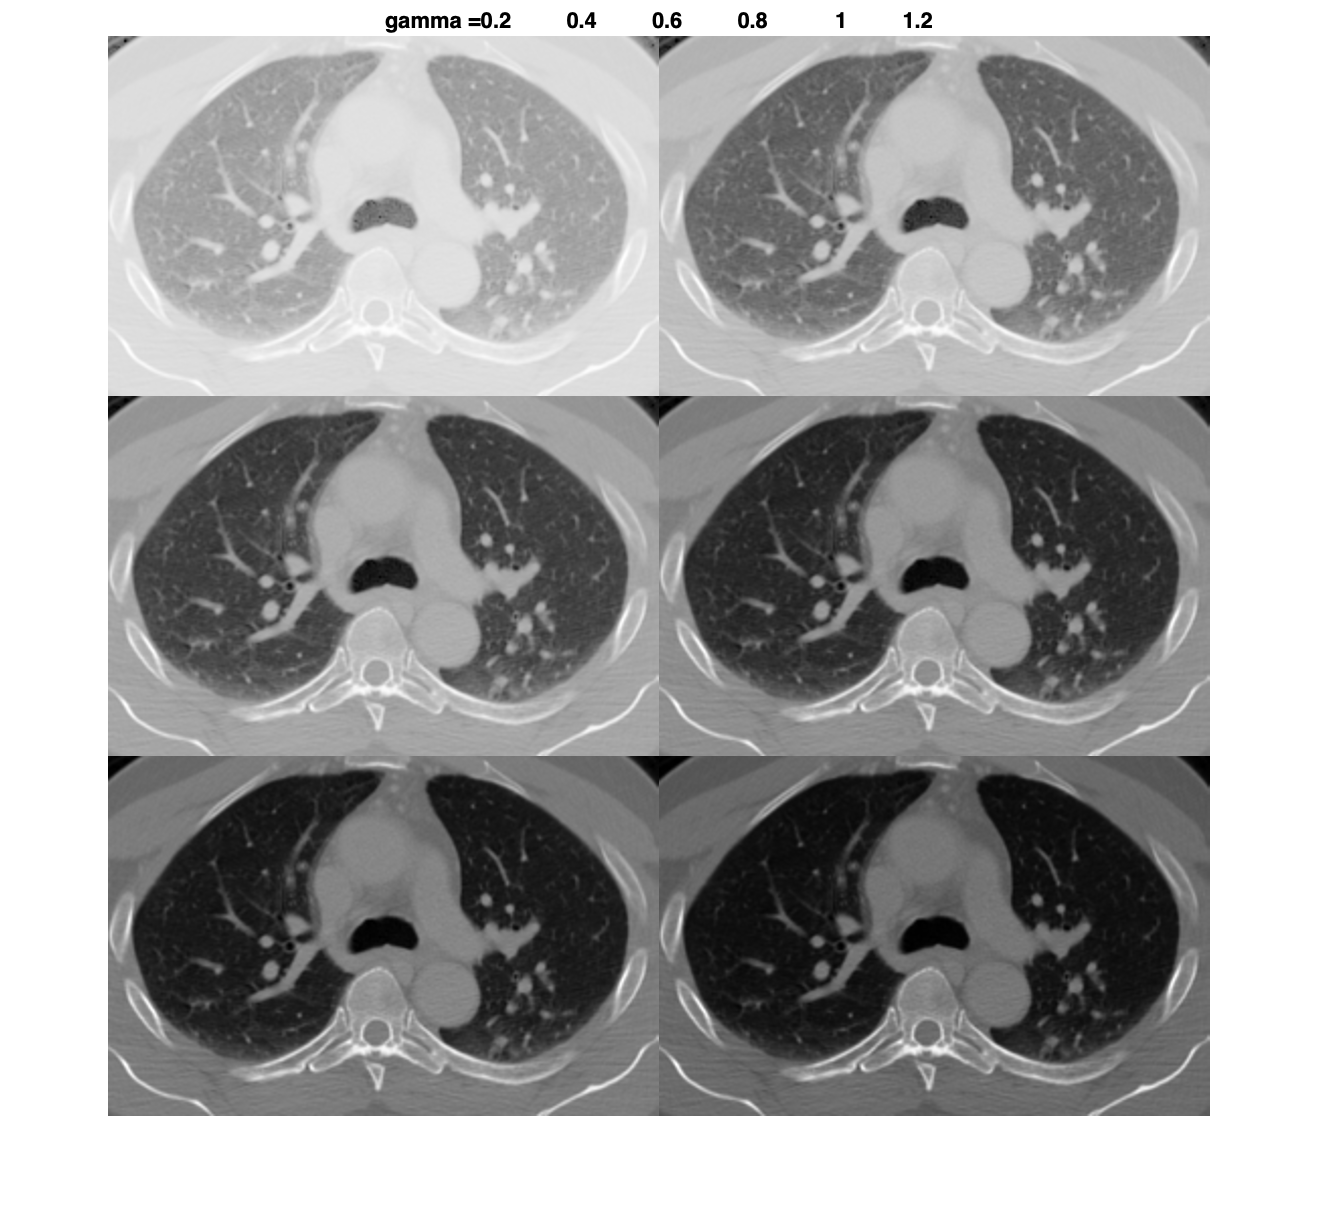

gamma_vect = 0.2:0.2:1.2;
LOW_IN = min(im(:));
HIGH_IN = max(im(:));
LOW_OUT = 0;
HIGH_OUT = 1;
im_adj= zeros(size(im,1),size(im,2),length(gamma_vect));
for i = 1:length(gamma_vect)
    im_adj(:,:,i) = imadjust(im, [LOW_IN HIGH_IN], [LOW_OUT HIGH_OUT], gamma_vect(i));
end

figure
montage(im_adj)
title(strcat('gamma = ', num2str(gamma_vect)))

Gamma was chosen to be 0.6 because image with this adjustment is able to better enhance lungs with details in respect to the background. `getps `function was used to manually select pixels belonging to the lungs, in order to create a mask to then perform segmentation.

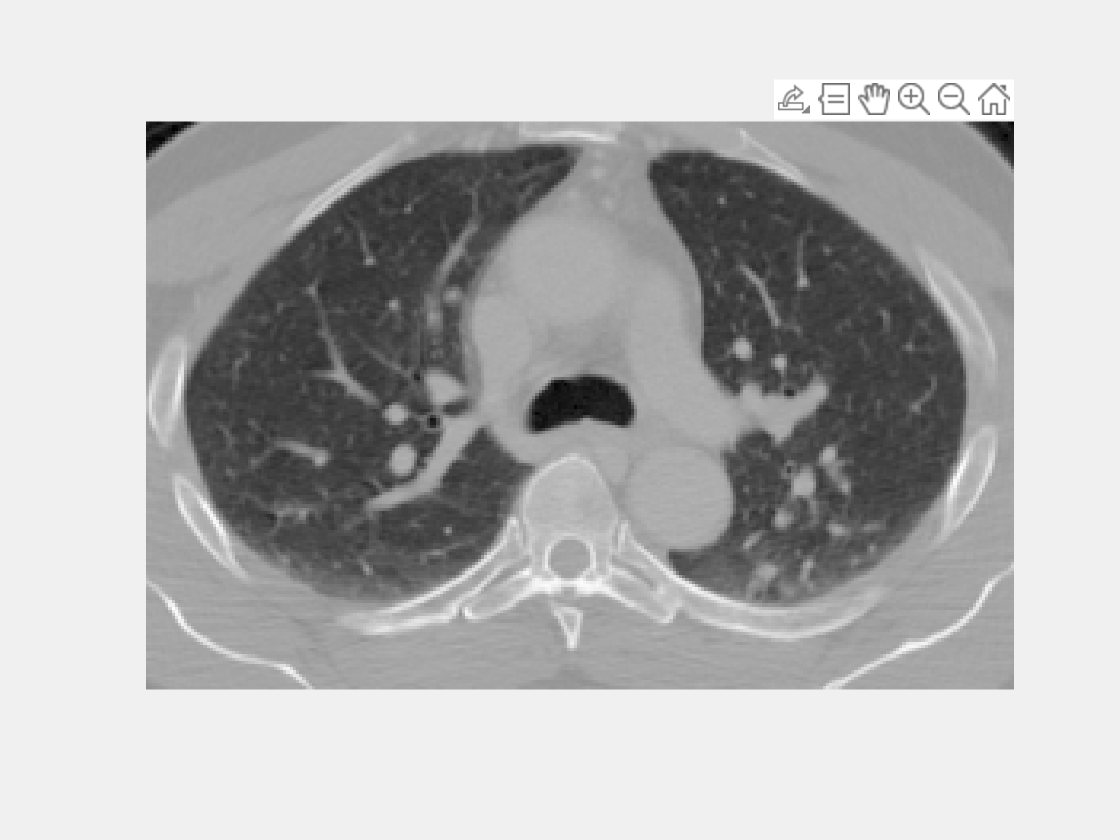

im_adj = imadjust(im, [LOW_IN HIGH_IN], [LOW_OUT HIGH_OUT], gamma_vect(3));
figure, imshow(im_adj, [], 'InitialMagnification', 'fit')
[X,Y] = getpts();

Histogram of the adjusted image was plotted to choose the right threshold (0.5) for T-transformation:


$$\left\lbrace \begin{array}{ll}
\mathrm{im}>0\ldotp 5 & 0\\
\mathrm{im}<0\ldotp 5 & \mathrm{keep}
\end{array}\right.$$


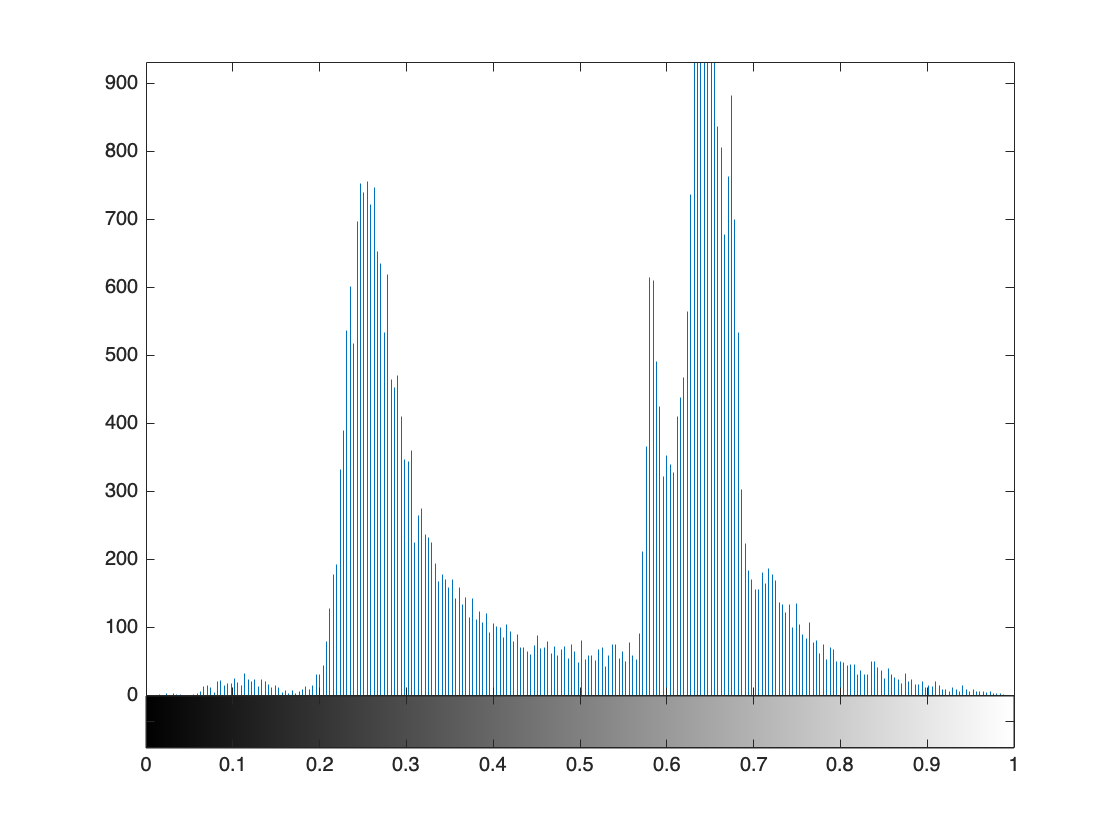

figure, imhist(im_adj)

### **Time instant 0**

Slices of interest were the ones containing lungs. Therefore, only the first 59 slices were taken into consideration.

Each slice was segmented by performing the normalisation, the adjustment and the conversion into binary (with `bwselect`) to obtain the mask. The image was finally multiplied by the mask.

segmented_image = zeros(size(im,1),size(im,2),59);
bw_t = zeros(size(im,1),size(im,2),59);
for i = 1:59
    im = vol{t}(:,:,i);
    im = imcrop(im, RECT);
    max_im = max(im(:));
    min_im = min(im(:));
    im = (im-min_im)./(max_im-min_im);
    LOW_IN = min(im(:));
    HIGH_IN = max(im(:));
    LOW_OUT = 0;
    HIGH_OUT = 1;
    im_adj = imadjust(im, [LOW_IN HIGH_IN], [LOW_OUT HIGH_OUT], gamma);

    im_adj(im_adj > 0.5) = 0;
    bw = bwselect(im_adj, X, Y);
    bw = imfill(bw,"holes"); %correction of holes
    segmented_image(:,:,i) = im.*single(bw);
    bw_t(:,:,i) = single(bw);
end

For each segmented slice, cross-sectional area over axial slices was calculated. Since area of lungs is usually different from left to right, they were plotted individually. As it can be seen from the graph below, left lung shows a smaller overall area due to the presence of the heart; the trend is similar.

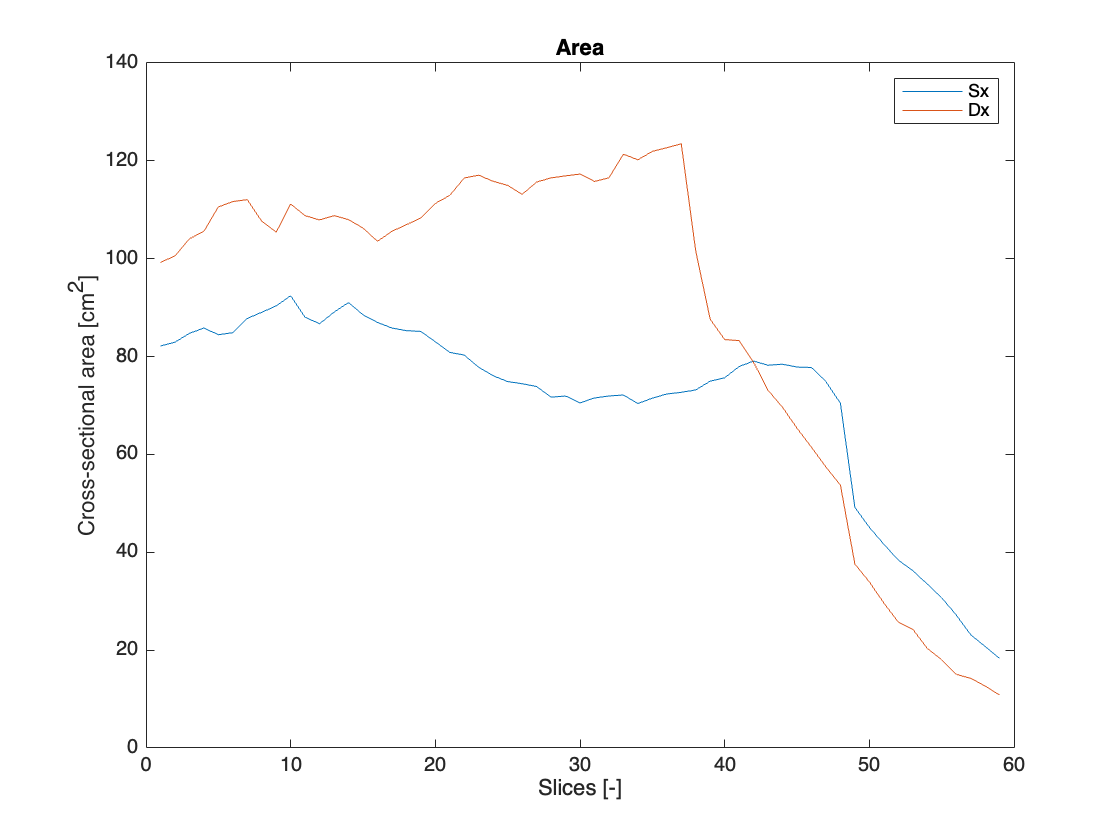

for i = 1:59
    slice = segmented_image(:,:,i);
    AreaLungsPixels = regionprops(logical(slice), 'Area');
    AreaLungsPixels = struct2table(AreaLungsPixels);
    spacingx = 0.976;
    spacingy = 0.976;
    spacingz = 2.5;
    unitar = spacingx*spacingy;
    AreaSx_as(i) = (AreaLungsPixels.Area(2)*unitar)*1e-2;
    AreaDx_as(i) = (AreaLungsPixels.Area(1)*unitar)*1e-2;
end

figure, plot(1:59, AreaSx_as, 1:59, AreaDx_as)
legend('Sx', 'Dx')
title('Area')
xlabel('Slices [-]')
ylabel('Cross-sectional area [cm^2]')

At slice 20, area is:

disp(['Area at slice 20 is: ', num2str(AreaSx_as(20)+AreaDx_as(20)), ' cm^2'])

Area at slice 20 is: 194.3255 cm^2


Until now, axial slices were considered. Coronal slices are now considered to calculate cross sectional area.

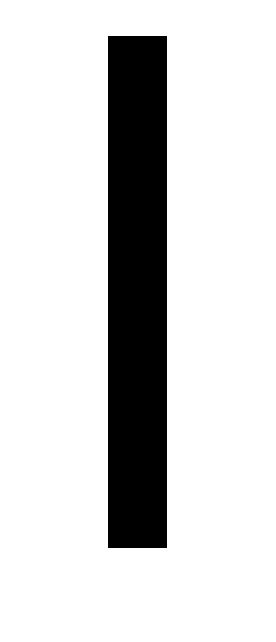

%figure, imshow(squeeze(vol{1}(200,:,:)), [])
%[X, Z] = getpts();
segmented_image_XZ = zeros(512,59, 145);
bw_t = zeros(512,59, 145);
for i = 175:320
    im_XZ = squeeze(vol{t}(i,:,1:59));
    max_im = max(im_XZ(:));
    min_im = min(im_XZ(:));
    im_XZ = (im_XZ-min_im)./(max_im-min_im);
    LOW_IN = min(im_XZ(:));
    HIGH_IN = max(im_XZ(:));
    LOW_OUT = 0;
    HIGH_OUT = 1;
    im_adj_XZ = imadjust(im_XZ, [LOW_IN HIGH_IN], [LOW_OUT HIGH_OUT], 0.4);

    im_adj_XZ(im_adj_XZ > 0.5) = 0;
    bw_XZ = bwselect(im_adj_XZ, X, Z);
    bw_XZ = imfill(bw_XZ,"holes"); %correction of holes
    segmented_image_XZ(:,:,i) = im_XZ.*single(bw_XZ);
    figure, imshow(segmented_image_XZ(:,:,i))
    bw_t(:,:,i) = single(bw_XZ);
end